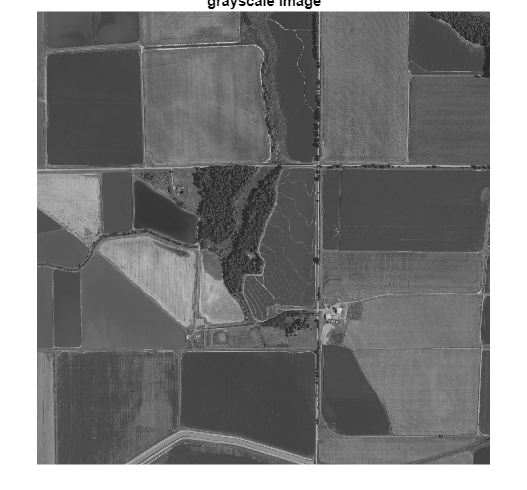

path = "C:\Users\harsh\OneDrive\Desktop\UNT Subjects\Feature Engineering\Update-2\Dataset\Development\field.jpg";
pathGT = "C:\Users\harsh\OneDrive\Desktop\UNT Subjects\Feature Engineering\Update-2\Dataset\GroundTruth\fieldGT.tif";
% Reading the image.
img = imread(path);
%converting to grayscale
grayImage = rgb2gray(img);
%reading the ground truth
imgGT=imread(pathGT);
imgGT=rgb2gray(imgGT);
% size of the image. 
[rows, col, colorscale] = size(grayImage);
% displaying grayscale image.
figure;
imshow(grayImage);
title('grayscale Image');

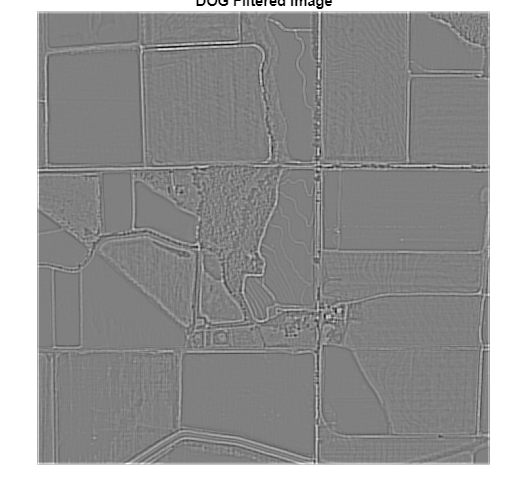

% creating gaussian blurrs with different sizes and sigma values.
gaussian1 = fspecial('Gaussian', 21, 15);
gaussian2 = fspecial('Gaussian', 21, 20);
%difference of gaussian.
diffOfGuas = gaussian1 - gaussian2;
%getting the 2D matrix by using convolution.
dogFilterImage = conv2(double(grayImage), diffOfGuas, 'same');
%displaying the convoluted image.
figure
imshow(dogFilterImage, []);
title('DOG Filtered Image');

disp(size(dogFilterImage));

        2048        2048



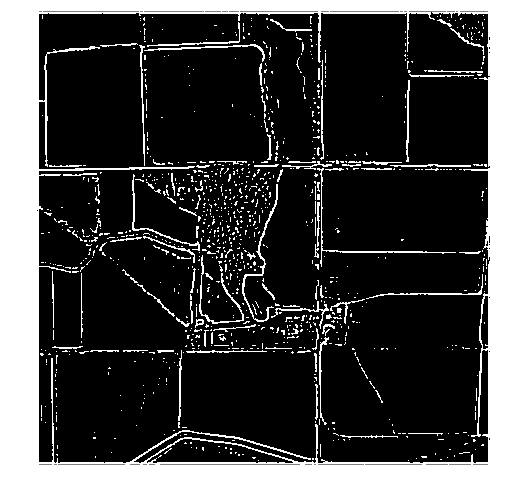

%converting the convoluted image to binary image.
bw =im2bw(dogFilterImage,0.15);
figure
imshow(bw);

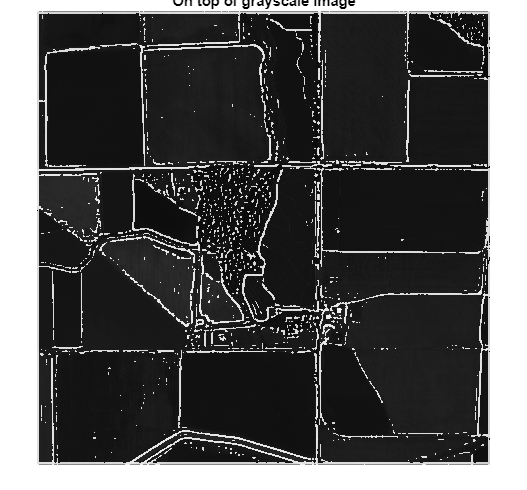

%Stacking the binary image on gray image.
H = vision.AlphaBlender;
grayImage = im2single(grayImage);
bw = im2single(bw);
Y = step(H,grayImage,bw);
%displaying the image
figure,imshow(Y);
title('On top of grayscale image');

%finding the accuracy
ssimval = ssim(bw,single(imgGT))*100;
%displaying the accuracy
fprintf('The SSIM score of the image is %f\n',ssimval)

The SSIM score of the image is 76.860313



accuracy = calculateAccuracy(bw,imgGT);
fprintf('The accuracy score of the image is %f\n',accuracy);

The accuracy score of the image is 91.825294



[precision, recall, f1_score] = findPrecisionRecallF1(bw, imgGT);
fprintf('The precision score of the image is %f\n',precision);

The precision score of the image is 14.216367


fprintf('The recall score of the image is %f\n',recall);

The recall score of the image is 44.597664


fprintf('The f1_score score of the image is %f\n',f1_score);

The f1_score score of the image is 21.560051
